Pipeline:

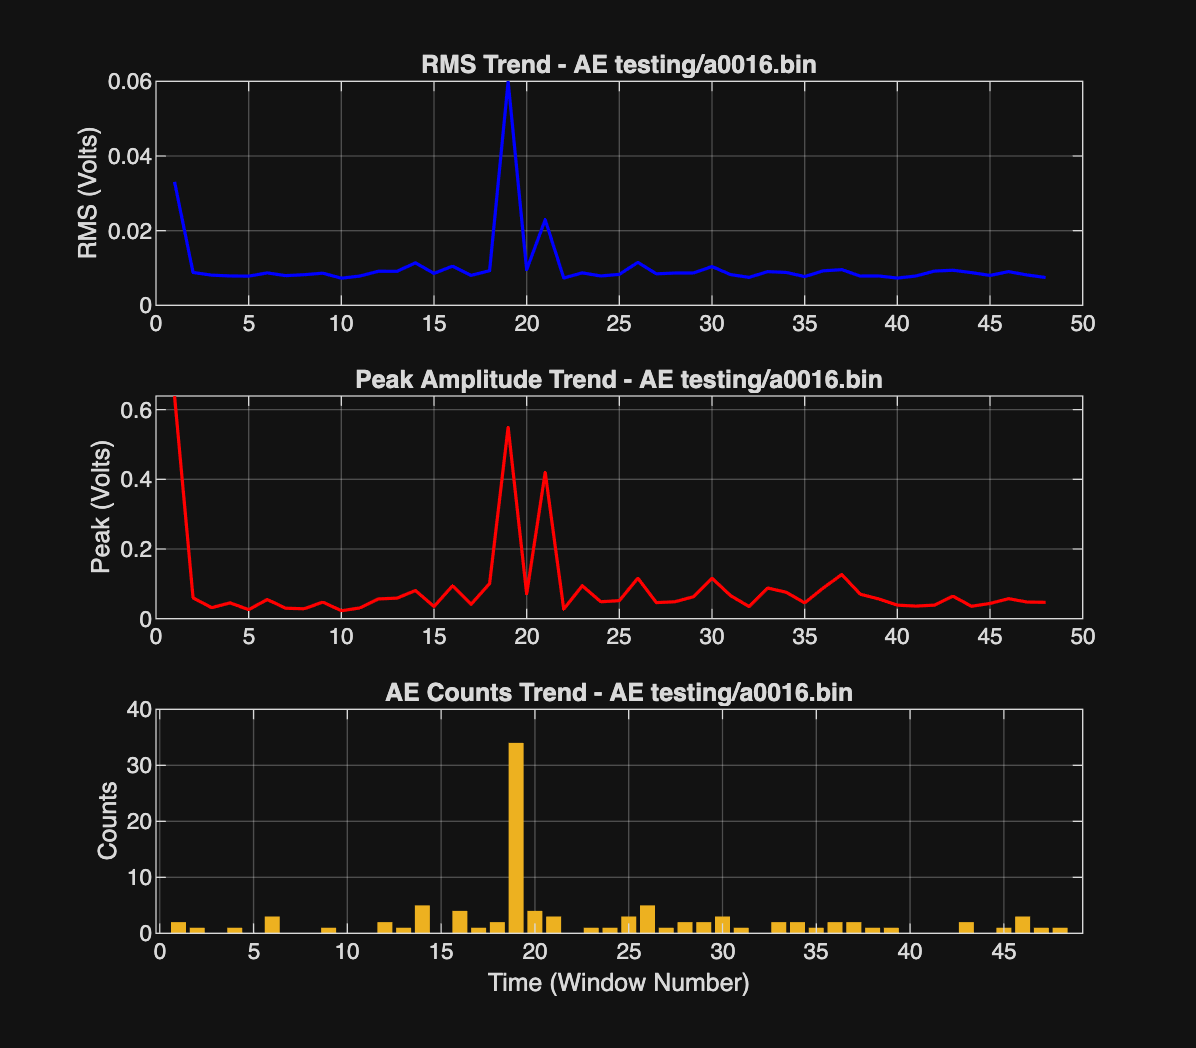

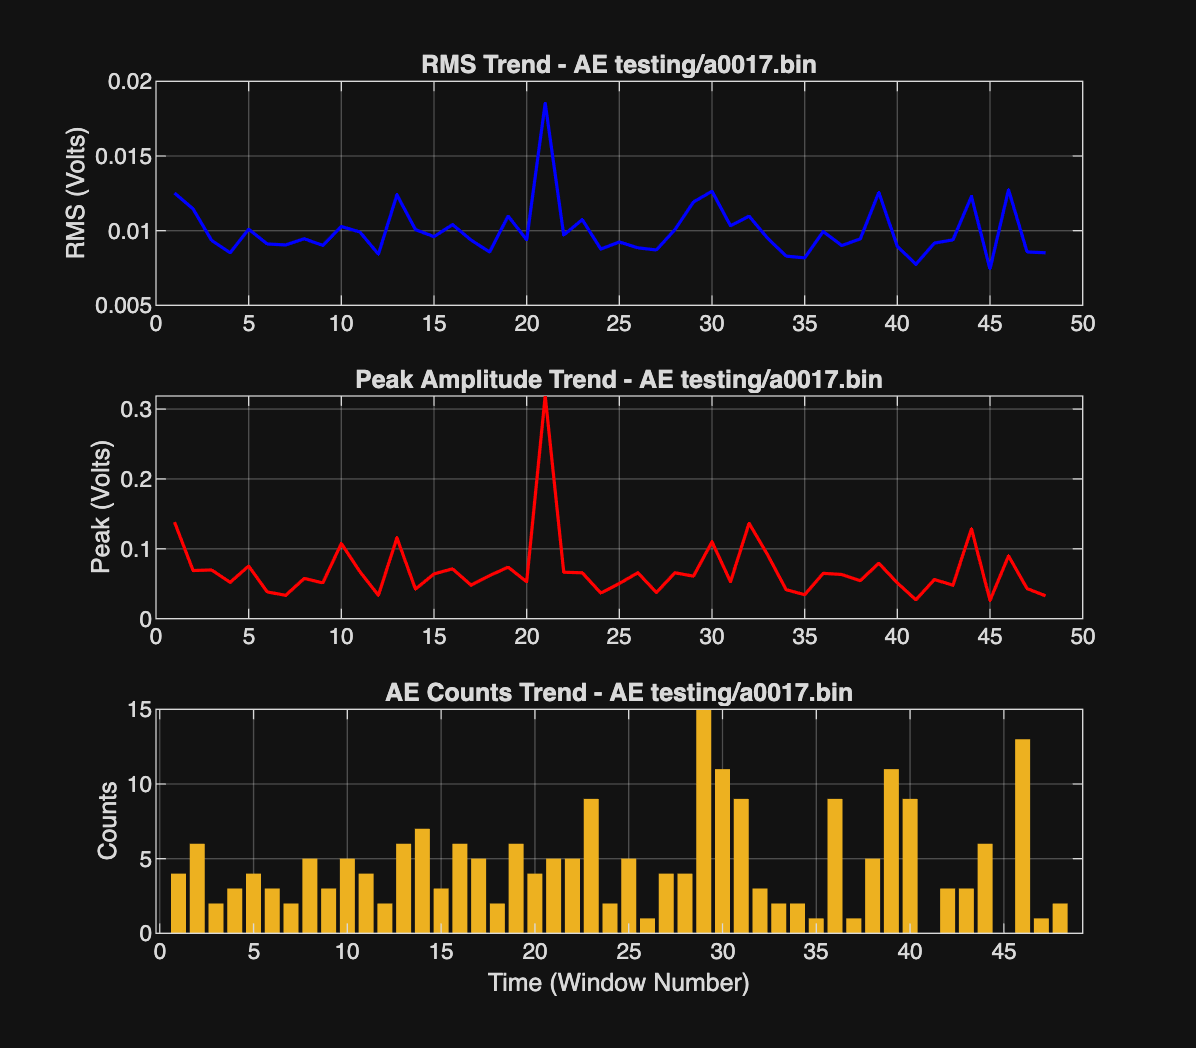

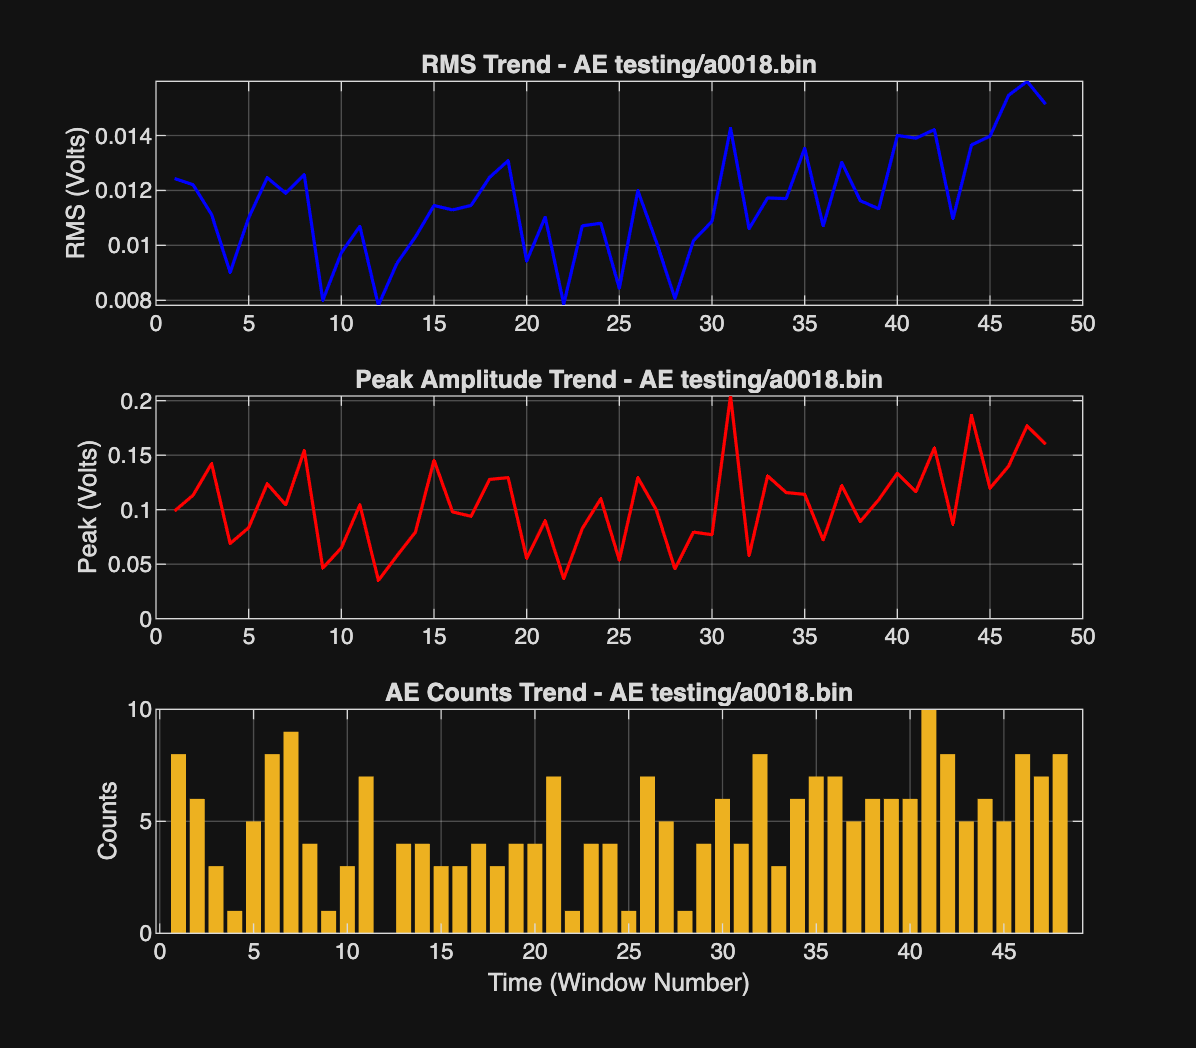

clear
clc
close all

fs = 4000;            
window_time = 0.1;        
overlap = 0.0;            

files = [
    "AE testing/a0016.bin"
    "AE testing/a0017.bin"
    "AE testing/a0018.bin"
];

win = round(window_time * fs);           
step = round(win * (1 - overlap));       

for f = 1:length(files)
    filename = files(f);
    fid = fopen(filename, 'rb');
    
    if fid == -1
        fprintf("Cannot open file: %s. Check your current MATLAB directory.\n", filename);
        continue
    end

    % Read the 16-bit binary integer data
    data = fread(fid, Inf, 'uint16');
    fclose(fid);

    % Convert ADC integers to real Voltage (Assuming 12-bit ADC, 3.3V reference)
    signal = double(data) / 4096 * 3.3;   
    
    % Remove DC offset (Center the signal around 0 Volts)
    signal = signal - mean(signal);
    
    N = length(signal);
    
    % Define the Threshold for AE Counts for this specific file
    Threshold = 3.0 * std(signal); 

    % Temporary arrays for the current file ONLY
    file_RMS = [];
    file_Peak = [];
    file_Counts = [];

    for i = 1:step:N-win
        segment = signal(i:i+win-1);
        
        % 1. RMS 
        val_rms = sqrt(mean(segment.^2));
        
        % 2. Peak Amplitude 
        val_peak = max(abs(segment));
        
        % 3. AE Counts 
        val_counts = sum(abs(segment) > Threshold);
        
        % Store features for this file
        file_RMS = [file_RMS; val_rms];
        file_Peak = [file_Peak; val_peak];
        file_Counts = [file_Counts; val_counts];
    end
    
    %% 3. CREATE A DEDICATED FIGURE FOR THIS FILE
    time_axis = 1:length(file_RMS);
    
    % Create a new figure window, slightly offset from the last one so they don't overlap perfectly
    figure('Name', sprintf('Analysis: %s', filename), 'Position', [50 + (f*50), 50 + (f*50), 800, 700]);
    
    % Plot 1: RMS 
    subplot(3, 1, 1);
    plot(time_axis, file_RMS, 'b', 'LineWidth', 1.2);
    ylabel('RMS (Volts)');
    title(sprintf('RMS Trend - %s', filename));
    grid on;
    
    % Plot 2: Peak Amplitude
    subplot(3, 1, 2);
    plot(time_axis, file_Peak, 'r', 'LineWidth', 1.2);
    ylabel('Peak (Volts)');
    title(sprintf('Peak Amplitude Trend - %s', filename));
    grid on;
    
    % Plot 3: AE Counts
    subplot(3, 1, 3);
    bar(time_axis, file_Counts, 'FaceColor', [0.9290, 0.6940, 0.1250], 'EdgeColor', 'none');
    ylabel('Counts');
    xlabel('Time (Window Number)');
    title(sprintf('AE Counts Trend - %s', filename));
    grid on;
    
end


%% 1. PARAMETERS & INITIALIZATION
fs = 4000;                
window_time = 0.1;        
overlap = 0.0;            

files = [
    "AE testing/a0016.bin"  % File 1: Has a massive impact spike
    "AE testing/a0017.bin"  % File 2: Clean Normal Baseline
    "AE testing/a0018.bin"  % File 3: Continuous Wear Anomaly
];

win = round(window_time * fs);           
step = round(win * (1 - overlap));       

% ==== BERT PARAMETERS ====
patch_size = 20;                         
num_patches = floor(win / patch_size);   
d_model = 64;                            
d_ff = 128;                              

% ==== AUTOENCODER PARAMETERS ====
input_dim = d_model;                     
hidden_dim = 16;                         

rng(42); % Lock random seed

% --- Init BERT Weights ---
W_proj = randn(patch_size, d_model) * 0.01;
pos_embed = randn(num_patches, d_model) * 0.01;
W_q = randn(d_model, d_model) * 0.01;
W_k = randn(d_model, d_model) * 0.01;
W_v = randn(d_model, d_model) * 0.01;
W_f1 = randn(d_model, d_ff) * 0.01;
W_f2 = randn(d_ff, d_model) * 0.01;

% --- Init Autoencoder Weights ---
W1_ae = randn(input_dim, hidden_dim) * 0.1;
b1_ae = zeros(1, hidden_dim);
W2_ae = randn(hidden_dim, input_dim) * 0.1;
b2_ae = zeros(1, input_dim);

%% 2. BERT ENCODING (FEATURE EXTRACTION)
bert_embeddings = [];
file_labels = [];
file_boundaries = [];
current_window = 0;

disp('Extracting BERT Embeddings...');

Extracting BERT Embeddings...


for f = 1:length(files)
    filename = files(f);
    fid = fopen(filename, 'rb');
    if fid == -1, continue; end

    data = fread(fid, Inf, 'uint16');
    fclose(fid);

    signal = double(data) / 4096 * 3.3;   
    signal = signal - mean(signal); % Remove DC offset
    N = length(signal);

    for i = 1:step:N-win
        segment = signal(i:i+win-1);
        segment = segment(:)'; 
        
        % [BERT FORWARD PASS]
        patches = reshape(segment, patch_size, num_patches)';
        X = patches * W_proj + pos_embed;                     
        
        Q = X * W_q; K = X * W_k; V = X * W_v;
        
        scores = (Q * K') / sqrt(d_model);                    
        scores_exp = exp(scores - max(scores, [], 2)); 
        attn_weights = scores_exp ./ sum(scores_exp, 2);
        Context = attn_weights * V;                           
        
        X_add = X + Context;
        mu1 = mean(X_add, 2); sig1 = std(X_add, 0, 2) + 1e-5;
        X_norm1 = (X_add - mu1) ./ sig1;
        
        FFN1 = max(0, X_norm1 * W_f1); % ReLU                       
        FFN2 = FFN1 * W_f2;
        
        X_out = X_norm1 + FFN2;
        mu2 = mean(X_out, 2); sig2 = std(X_out, 0, 2) + 1e-5;
        X_norm2 = (X_out - mu2) ./ sig2;
        
        window_embedding = mean(X_norm2, 1); % Pool patches                  
        
        bert_embeddings = [bert_embeddings; window_embedding];
        file_labels = [file_labels; f];
        current_window = current_window + 1;
    end
    file_boundaries = [file_boundaries; current_window];
end

%% 3. DATA PREPARATION & AUTOENCODER TRAINING
disp('Training Autoencoder on File 2 (Clean Baseline)...');

Training Autoencoder on File 2 (Clean Baseline)...



% CRITICAL: Only train on File 2 (a0017.bin)
train_idx = (file_labels == 2);
X_train_raw = bert_embeddings(train_idx, :);
X_all_raw = bert_embeddings;

% Normalize based on File 2 characteristics
mu_train = mean(X_train_raw);
sig_train = std(X_train_raw) + 1e-8;

X_train = (X_train_raw - mu_train) ./ sig_train;
X_all = (X_all_raw - mu_train) ./ sig_train;

epochs = 1000;
learning_rate = 0.05;
N_train = size(X_train, 1);

for ep = 1:epochs
    % Forward Pass
    Z1 = X_train * W1_ae + b1_ae;
    A1 = max(0, Z1);           
    Z2 = A1 * W2_ae + b2_ae;
    X_pred = Z2;               
    
    % Backprop
    error = X_pred - X_train;
    dZ2 = 2 * error / N_train;
    dW2 = A1' * dZ2; db2 = sum(dZ2, 1);
    dA1 = dZ2 * W2_ae';
    dZ1 = dA1 .* (Z1 > 0);     
    dW1 = X_train' * dZ1; db1 = sum(dZ1, 1);
    
    W1_ae = W1_ae - learning_rate * dW1; b1_ae = b1_ae - learning_rate * db1;
    W2_ae = W2_ae - learning_rate * dW2; b2_ae = b2_ae - learning_rate * db2;
end

%% 4. ANOMALY DETECTION (RECONSTRUCTION ERROR)
disp('Calculating Reconstruction Error for all files...');

Calculating Reconstruction Error for all files...



Z1_all = X_all * W1_ae + b1_ae;
A1_all = max(0, Z1_all);
Z2_all = A1_all * W2_ae + b2_ae;
X_all_pred = Z2_all;

% THIS IS THE MISSING VARIABLE
reconstruction_error = mean((X_all - X_all_pred).^2, 2);

% Calculate Threshold based on File 2 normal variance
normal_errors = reconstruction_error(train_idx);
threshold = mean(normal_errors) + 3 * std(normal_errors);

%% 5. EMBEDDED DECISION LOGIC (Microprocessor Simulation)
disp('Running Decision Logic...');

Running Decision Logic...


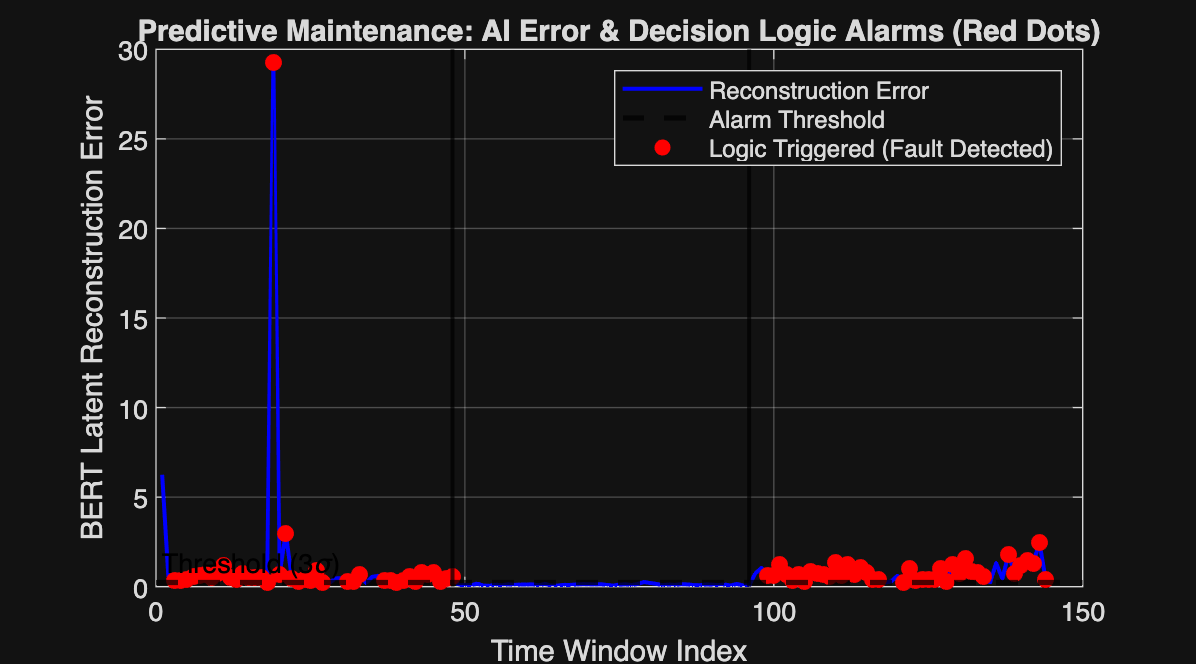

consecutive_alarms = 0;
required_consecutive_windows = 3; 
alarm_history = zeros(length(reconstruction_error), 1);

for i = 1:length(reconstruction_error)
    if reconstruction_error(i) > threshold
        consecutive_alarms = consecutive_alarms + 1;
    else
        consecutive_alarms = 0;
    end
    
    if consecutive_alarms >= required_consecutive_windows
        alarm_history(i) = 1; 
    end
end

figure('Name', 'BERT-Autoencoder Decision Logic', 'Position', [100, 100, 900, 500]);

plot(1:length(reconstruction_error), reconstruction_error, 'b', 'LineWidth', 1.5);
hold on; grid on;

yline(threshold, 'k--', 'Threshold (3\sigma)', 'LineWidth', 2, 'LabelHorizontalAlignment', 'left');

alarm_indices = find(alarm_history == 1);
scatter(alarm_indices, reconstruction_error(alarm_indices), 40, 'r', 'filled');

for b = 1:length(file_boundaries)-1
    xline(file_boundaries(b), 'k-', 'LineWidth', 1.5);
end

xlabel('Time Window Index');
ylabel('BERT Latent Reconstruction Error');
title('Predictive Maintenance: AI Error & Decision Logic Alarms (Red Dots)');
legend('Reconstruction Error', 'Alarm Threshold', 'Logic Triggered (Fault Detected)');